# Labb 3 Förberedelser

#### Task 1

% im = imread('characterTestPattern.tif');
% cTP = im2double(im);
% 
% A = fftshift(fft2(cTP));
% Spec1=log(1+abs(A)); % 1 is added because 𝒍𝒐𝒈is not defined at 𝟎
% Spec1=Spec1/max(Spec1(:));
% imshow(Spec1)
% 
% cTP_shift=circshift(cTP,[100,-200]);
% imshow(cTP_shift)

#### Task 2

% B = fftshift(fft2(cTP_shift));
% Spec2=log(1+abs(B)); % 1 is added because 𝒍𝒐𝒈is not defined at 𝟎
% Spec2=Spec2/max(Spec2(:));
% imshow(Spec2)
% 
% cTP_rot = imrotate(cTP,15,'bicubic');
% imshow(cTP_rot)

#### Task 4

% C = fftshift(fft2(cTP_rot));
% Spec3=log(1+abs(C)); % 1 is added because 𝒍𝒐𝒈is not defined at 𝟎
% Spec3=Spec3/max(Spec3(:));
% imshow(Spec3)

#### Task 5

% im2 = imread('characterTestPattern_2.tif');
% cTP2 = im2double(im2);
% 
% D = fftshift(fft2(cTP2));
% Spec4=log(1+abs(D)); % 1 is added because 𝒍𝒐𝒈is not defined at 𝟎
% Spec4=Spec4/max(Spec4(:));
% imshow(Spec4)
% 

#### Task 9

% im3 = imread('characterTestPattern_3.tif');
% cTP3 = im2double(im3);
% 
% E = fftshift(fft2(cTP3));
% Spec5=log(1+abs(E)); % 1 is added because 𝒍𝒐𝒈is not defined at 𝟎
% Spec5=Spec5/max(Spec5(:));
% imshow(Spec5)

## Part 2: Period and frquency

#### Task11

% v2 = imread('verticalbars_2.tif');
% imshow(v2);
% 
% F = fftshift(fft2(v2));
% Spec6=log(1+abs(F)); % 1 is added because 𝒍𝒐𝒈is not defined at 𝟎
% Spec6=Spec6/max(Spec6(:));
% imshow(Spec6)

#### Task 12

% v4 = imread('verticalbars_4.tif');
% imshow(v4);
% F = fftshift(fft2(v4));
% Spec7=log(1+abs(F)); % 1 is added because 𝒍𝒐𝒈is not defined at 𝟎
% Spec7=Spec7/max(Spec7(:));
% imshow(Spec7)

## Part 3: The importance fo the spectrum and the phase angle

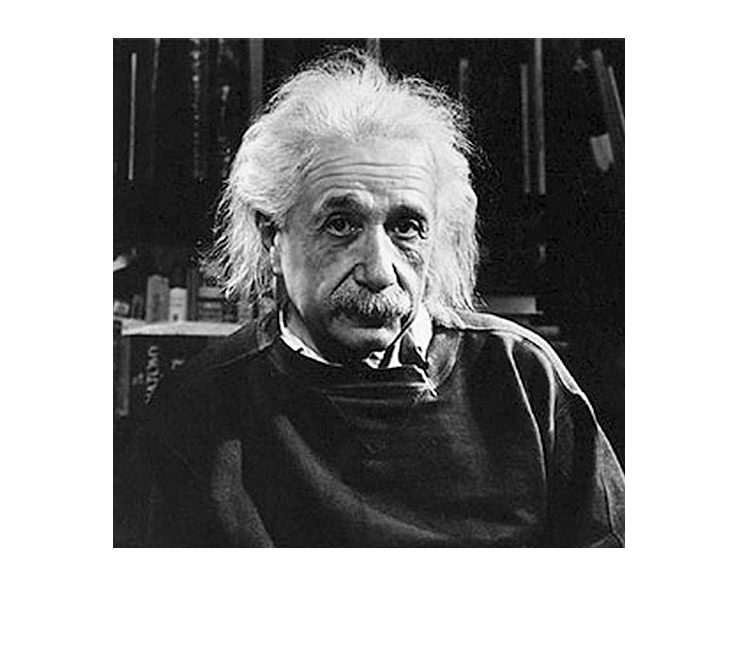

% ime = imread('Einstein1.jpg');
% ime2 = imread('Einstein2.jpg');
% E1 = im2double(ime);
% E2 = im2double(ime2);
% imshow(E1);

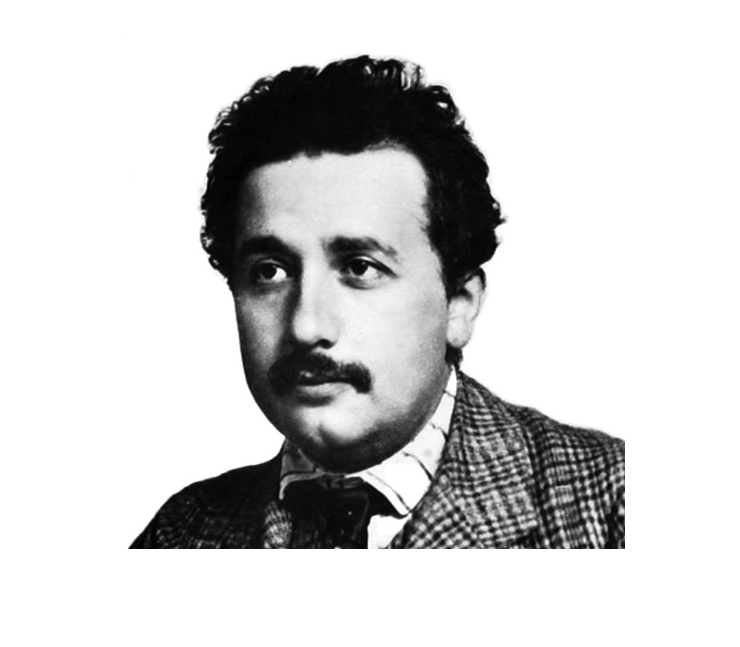

% imshow(E2);

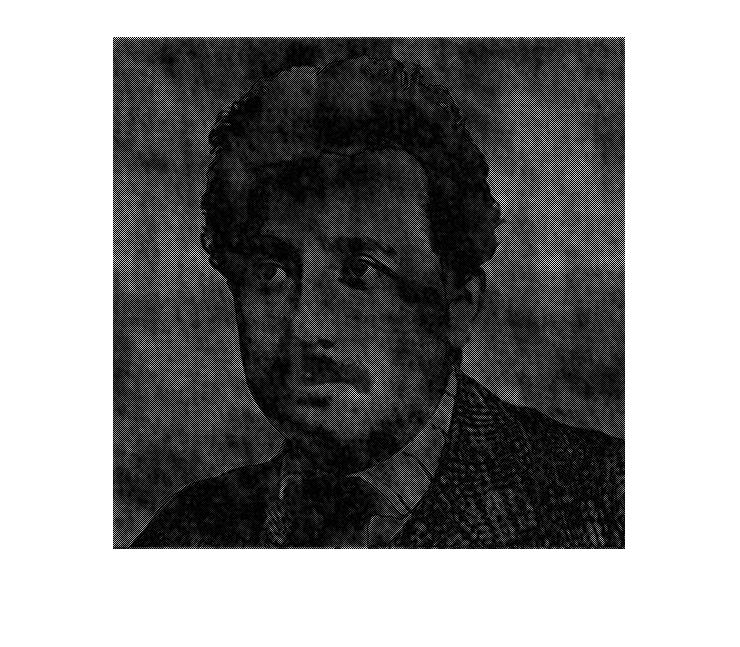

% 
% %Fourier spectrums:
% F1 = fftshift(fft2(E1));
% F2 = fftshift(fft2(E2));
% % Phase angles
% ang1 = angle(F1);
% ang2 = angle(F2);
% S1 = abs(F1);
% S2 = abs(F2);
% % 
% Prob14 = real(ifft2(S1.*exp(i * ang2)));
% imshow(Prob14)

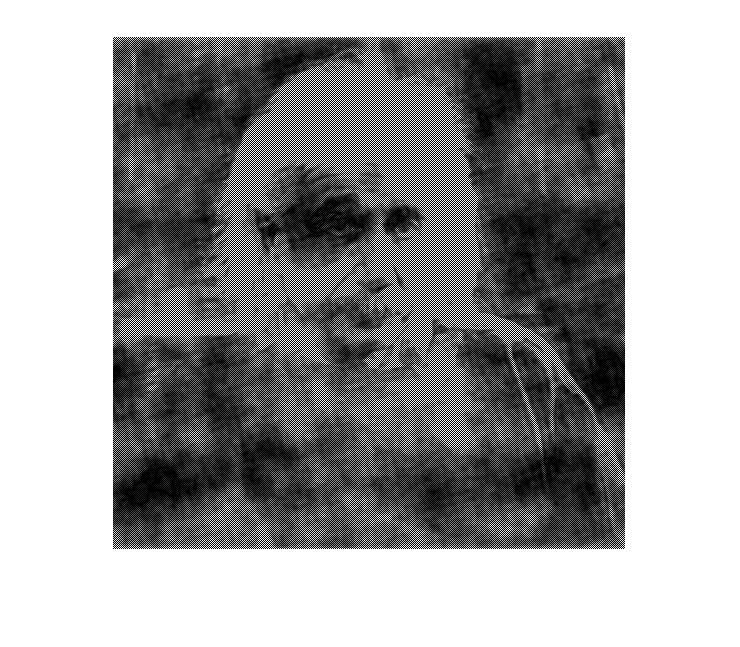

% 
% Prob15 = real(ifft2(S2.*exp(i * ang1)));
% imshow(Prob15)

Hur funktionerna funkar

𝒇𝒇𝒕𝟐(𝑿)returns the two-dimensional Fourier transform of matrix 𝑿

𝒊𝒇𝒇𝒕𝟐(𝑭)returns the two-dimensional inverse Fourier transform of matrix 𝐹

𝒇𝒇𝒕𝒔𝒉𝒊𝒇𝒕(𝑭)shifts zero-frequency component to center of spectrum

𝒊𝒇𝒇𝒕𝒔𝒉𝒊𝒇𝒕is the inverse of fftshift`74`

𝒂𝒃𝒔(𝑭)returns the magnitude of the elements (i.e. the spectrum) of 𝑭

𝒂𝒏𝒈𝒍𝒆(𝑭)returns the phase angles of 𝑭